# **Ejercicio Uno**

## **Valores de Entrada**

#### **Imagenes**

orginalImage = im2gray(imread('images/granos.png'));
originalImageNeg = im2gray(imread('images/mamografia.tif'));
originalImageLog = im2gray(imread('images/ImagenFourier.png'));
originalImageGamma = im2gray(imread('images/resonancia.tif'));
originalImageEq = im2gray(imread('images/granos.png'));

#### **Constantes (**transformación logaritmica y gamma)

constLog = 40; % Constante de la transformación negativa
constGamma = 40; 

#### Valor Gamma (transformación gamma)

gammaValue = 0.7;

## **Ejercicio A**

#### **Desplegar la imagen original y su histograma **

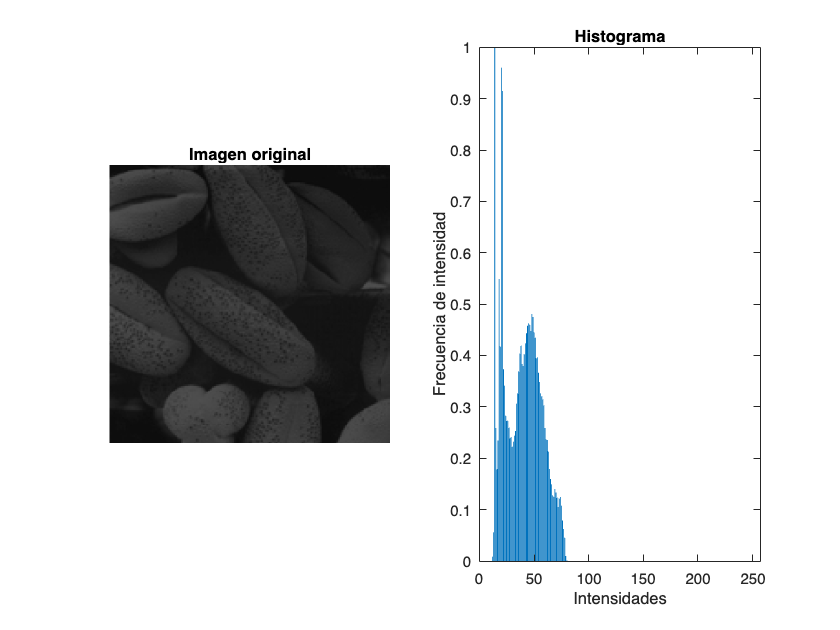

originalHistogram = histogramValues(orginalImage);
equalizedHistogram01 = equalizeHistogram(originalHistogram);
showHistogram(orginalImage, equalizedHistogram01, 'Imagen original');

## **Ejercicio B**

#### **Imagen con transformación negativa**

Aplicar una transformación negativa a la imagen leida en A.

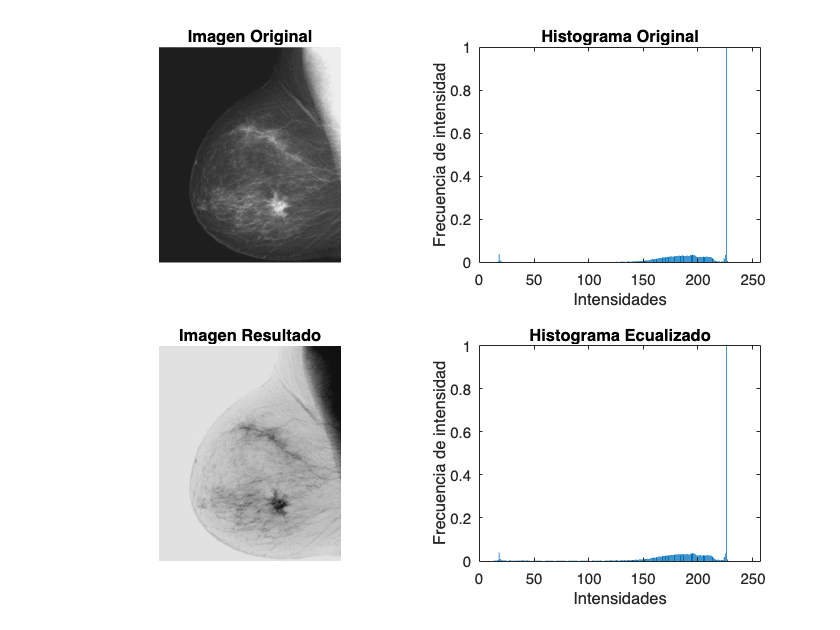

negImage = negativeTransformation(originalImageNeg);
histogram = histogramValues(negImage);
equalizedHistogram = equalizeHistogram(histogram);
%showHistogram(negImage, equalizedHistogram, 'Imagen Negativa');
showEqualization(originalImageNeg, equalizeHistogram(histogram), negImage, equalizedHistogram);

#### **Imagen con transformación logaritmica**

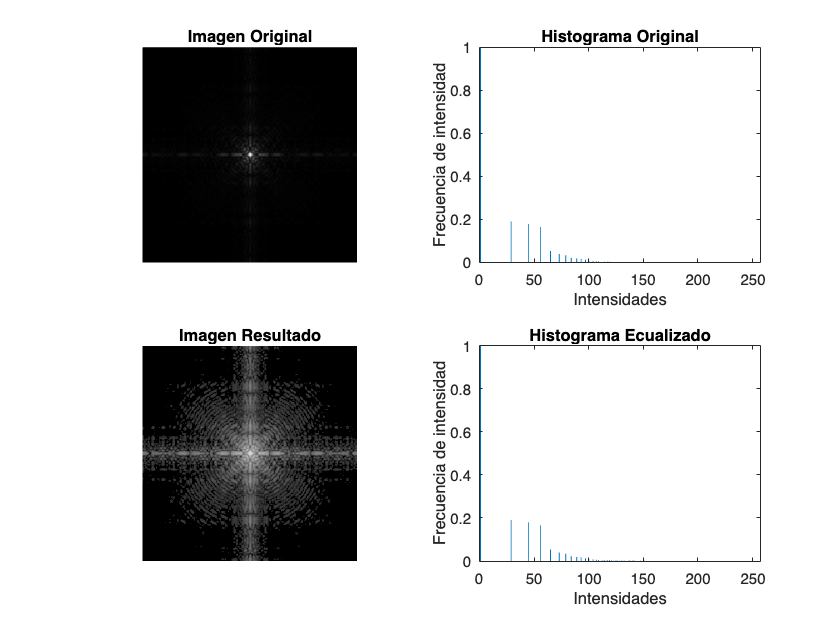

logImage = logTransformation(originalImageLog,constLog);
histogram = histogramValues(logImage);
equalizedHistogram = equalizeHistogram(histogram);
%showHistogram(logImage, equalizedHistogram, 'Imagen Logaritmica');
showEqualization(originalImageLog, equalizeHistogram(histogram), logImage, equalizedHistogram);

#### **Imagen con transformación gamma**

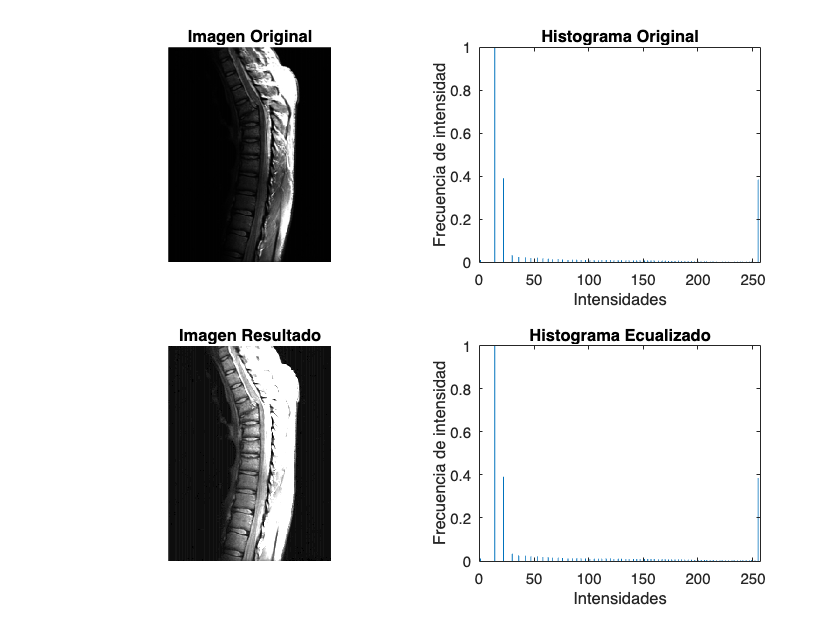

gammaImage = gammaTransformation(originalImageGamma,constGamma, gammaValue);
histogram = histogramValues(gammaImage);
equalizedHistogram = equalizeHistogram(histogram);
%showHistogram(gammaImage, equalizedHistogram, 'Imagen Gamma');
showEqualization(originalImageGamma, equalizeHistogram(histogram) ...
    , gammaImage, equalizedHistogram);

#### **Ecualización de una imagen**

histogram = histogramValues(originalImageEq);
imageEqualized = equalize(originalImageEq,histogram);
histogram = histogramValues(imageEqualized)

histogram =     35
   234
     0
     0
     0
     0
     0
     0
     0
     0


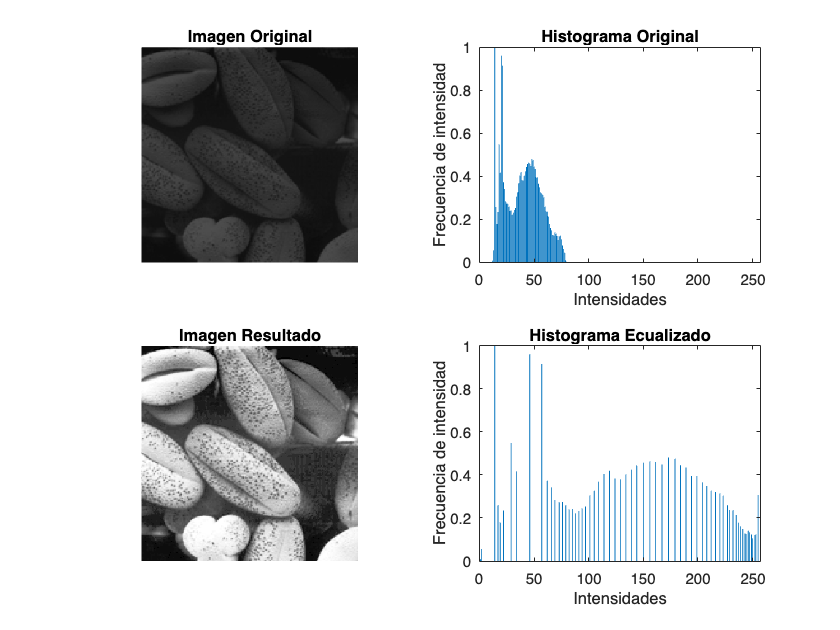

equalizedHistogram02 = equalizeHistogram(histogram);

showEqualization(orginalImage, equalizedHistogram01, imageEqualized, equalizedHistogram02);

## Funciones

#### histogramValues

Función que dada una imagen genera los valores para la elaboración de un histograma ecualizado.

function hist = histogramValues(img)
    [rows, cols] = size(img); 
    hist = zeros(256,1); 
    for r = 1:rows
    for c = 1:cols
          value = img(r,c);  
          hist(value+1) = hist(value+1) + 1;
    end
    end
end

#### histogramEqualized

Función que dado un histograma se ecualiza contabilizando el total de elementos

function hist = equalizeHistogram(originalHist)
    maxValue = max(originalHist);
    hist = originalHist/maxValue; 
end

#### equalize

Función que dado un histograma y una imagen, devuelve una imagen ecualizada

function imageEqualized = equalize(im,histogram)
    [row,column] = size(im);

    imageEqualized = zeros(row,column, 'uint8');
    quantityElements = row*column;

  
    probabilities=zeros(1,256);
    cumulativeProbability = zeros(1,256); 
    transformation= zeros(1,256);

    % Calcula la probabilidad sobre cada elemento del histograma
    for i=1:256
        probabilities(i)=histogram(i)/quantityElements;
    end

    %acumulada(1) = probabilities(1); 
    
    % Calcula la probabilidad acumulada (suma de la anterior) 
    for i = 2:256
        cumulativeProbability(i) = cumulativeProbability(i-1) + probabilities(i);
    end

    %disp(cumulativeProbability);
    
    % Calcula el nuevo valor de cada probabilidad
    for i=1:256
        transformation(i) = cumulativeProbability(i)*256;
    end
    
    % Se asigna un nuevo valor a los elementos la imagen
    for i=1:row
        for j=1:column
            imageEqualized(i,j)=transformation(im(i,j)+1);
        end
    end
    
end

#### **negativeTransformation**

Función que dada una imagen, le aplica una transformación negativa

Pone r

function negImage = negativeTransformation(img)
    [rows, cols] = size(img); 
    negImage = zeros(rows,cols,'uint8');
    [rows, cols] = size(img); 
    for r = 1:rows
       for c = 1:cols
          negImage(r,c) = 255 - img(r,c); 
       end
    end
end

#### logTransformation

Función que dada una imagen, le aplica una transformación logartimica

function logImage = logTransformation(img, constant)
    [rows, cols] = size(img); 
    logImage = zeros(rows,cols,'uint8');
    for r = 1:rows
       for c = 1:cols
          oldValue = double(img(r,c));
          logImage(r,c) = constant*log(oldValue+1); 
       end
    end
end

#### gammaTransformation

Función que dada una imagen, le aplica una transformación gamma 

function gammaImage = gammaTransformation(img, constant, gamma)
    [rows, cols] = size(img); 
    gammaImage = zeros(rows,cols,'uint8');
    for r = 1:rows
       for c = 1:cols
          newValue = (constant * double(img(r,c)))^gamma; 
          gammaImage(r,c) = uint8(newValue); 
       end
    end
end

#### showHistogram

Función que crea una figura con un histograma e imagen

function showHistogram(image, histogram, labelImage)
    figure;
    subplot(1, 2, 1);
    imshow(image);
    title(labelImage);
    
    subplot(1, 2, 2);
    bar(histogram);
    title('Histograma');
    xlabel('Intensidades');
    ylabel('Frecuencia de intensidad')
    title('Histograma');
end

#### showEqualization

Función que crea una cuadricula con la imagen original, su histograma, imagen ecualizada y el histograma ecualizado, Cada elemento con una etiqueta.

function showEqualization(originalImage, histogram, newImage, newHistogram)
    figure;
    subplot(2, 2, 1);
    imshow(originalImage);
    title('Imagen Original');
    
    subplot(2, 2, 2);
    bar(histogram);
    title('Histograma');
    xlabel('Intensidades');
    ylabel('Frecuencia de intensidad')
    title('Histograma Original');

    subplot(2, 2, 3);
    imshow(newImage);
    title('Imagen Resultado');

    subplot(2, 2, 4);
    bar(newHistogram);
    title('Histograma');
    xlabel('Intensidades');
    ylabel('Frecuencia de intensidad')
    title('Histograma Ecualizado');
end